3. Diseñe un filtro pasa-altas de 51 coeficientes, a partir de 8pi/10. 

Filtro en la frecuencia de $-\pi \;$a $\pi$ con el filtro hasta $\omega_f >\frac{8\pi }{10}$

## Generacion de ventana cuadrada 

Se define un tiempo de observacion de 625 segundos por ser $-\pi ,\pi$ el rango es $2\pi$

bound =[-pi,pi]; % 2pi range lenght
obs = 100; % 100 segundos 

## Parametros del filtrado

#### Frecuencias de corte en radianes

%Puntos de corte del filtro
numerador_inicio = 3;
denominador_inicio =7;
numerador_final   = 4;
denominador_final = 7;

#### Numero de coeficinetes del filtro 

coeff       = 22;

Al manejar con los slider se procura tener cuidado con los valores por ello programamos la siguiente excpección. 

value_begin = numerador_inicio*pi/denominador_inicio;
value_end   = numerador_final*pi/denominador_final;
if value_begin > value_end
    ME = MException( 'myComponent:inputError','Invalid sliders begin shall be smaller than end');
    throw(ME)
end
cut_begin = value_begin;
cut_end = value_end;

Proseguimos con el diseño del filtro con los puntos de corte definidos por los sliders. 

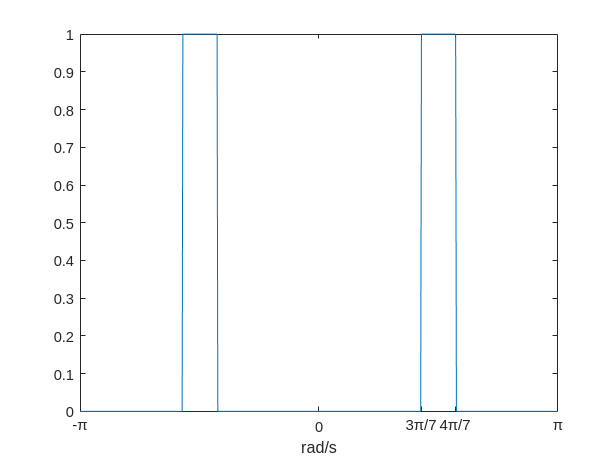

cut_points =  [(-1)*cut_end (-1)*cut_begin cut_begin cut_end];
cut_str    =  [strcat(string(numerador_inicio),'\pi/',string(denominador_inicio))
              strcat(string(numerador_final),'\pi/',string(denominador_final))];

% tiempo de observacion 100s * 2pi = 625 muestras
space = bound(1):1/obs:bound(2)+1/100; 
%inicia señal de filtro en 0 
rad_space = zeros(1,length(space));

%parametros limite en la señal
%cut_freq_id se utilizara despues para el corte en tiempo tambien
cut_freq_id = []; 
%Counter for cutting points
cnt = 0;

%Iterate over all cutting points and when reach a pair of poins mod(cnt,2)
%assign them the frecuency square window. 

for section = cut_points % Ventana limits
   temp = find(space == interp1(space,space,section,'nearest'));%index in linespace
   cut_freq_id = [cut_freq_id temp]; % add index of limits
   cnt = cnt +1;
   if(mod(cnt,2) == 0) % Cnt is a pair of cutting values
       rad_space(cut_freq_id(cnt-1):cut_freq_id(cnt)) = 1;
   end
end

%Parametros de la grafica
plot(space,rad_space)
xlim([-pi pi])
xticks([-pi 0 cut_begin cut_end pi])
xticklabels({'-\pi','0',cut_str(1),cut_str(2),'\pi'})
xlabel('rad/s')

Converimos las ventanas de frecuencia a tiempo. 

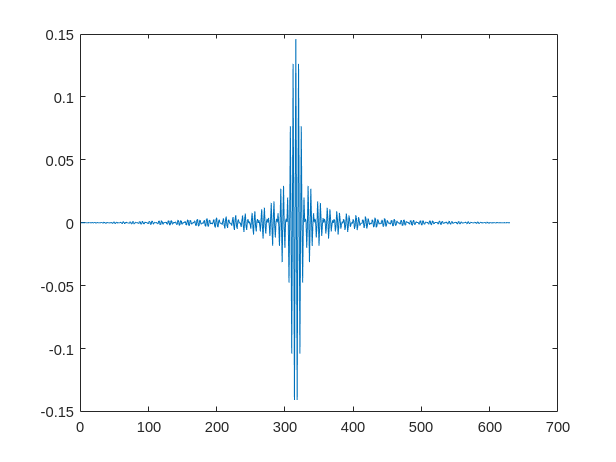

ventana_tiempo = real(ftot(rad_space));
plot(ventana_tiempo)

Generacion de ventanas en tiempo, con 51 coeficientes. Y una venta de hamming

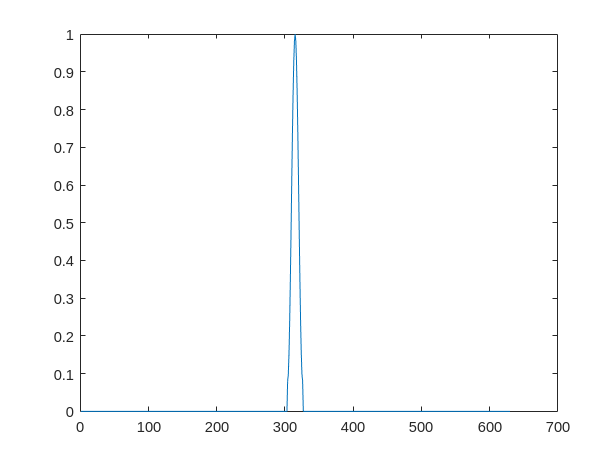

ventanacuad = zeros(1,length(space));
middle      = (length(space))/2;
left        = int32((middle-coeff/2));
right       = int32((middle+coeff/2)); 
ventanacuad(left:right) = hamming(coeff+1)';
plot(ventanacuad)

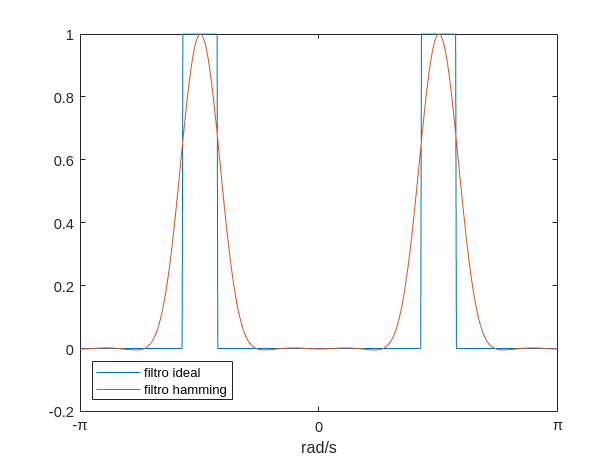

filtro_cuad=ventana_tiempo.*ventanacuad;
plot(space,rad_space);
hold on
plot(space,real(ttof(filtro_cuad))/max(real(ttof(filtro_cuad))))
xlim([-pi pi])
xticks([-pi 0 pi 2*pi 3*pi])
xticklabels({'-\pi','0','\pi'})
xlabel('rad/s')
legend({'filtro ideal','filtro hamming'},'Location','southwest')
hold off